imgarray_dark=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_dsnu',640,480);
imgarray_50=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_prnu',640,480);

images_dark=cellarray_to_3d_matrix(imgarray_dark);
images_50=cellarray_to_3d_matrix(imgarray_50);

% K=0.098;
% tic;
% [DSNU,PRNU,sv_50,sv_dark] = DSNU_PRNU_3dmat(images_dark,images_50,K)
% toc;

imgarray_mv=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480);

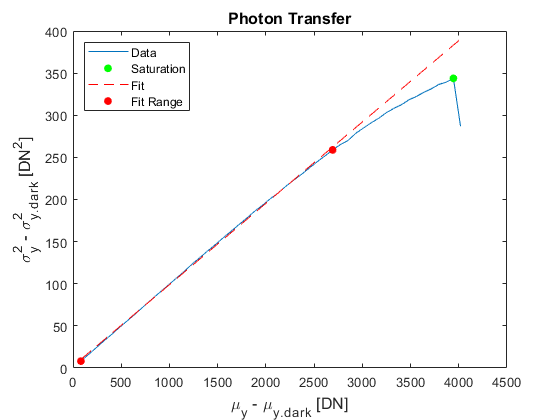

mean_dark = 29.4063

var_dark = 9.0780

K = 0.0966

[mean_dark,var_dark,K] = photonTransfer_curve_EMVA1288_mono(imgarray_mv)

temp_dark=compute_temporaldarknoise(var_dark,(1/12),K)

temp_dark = 31.0596

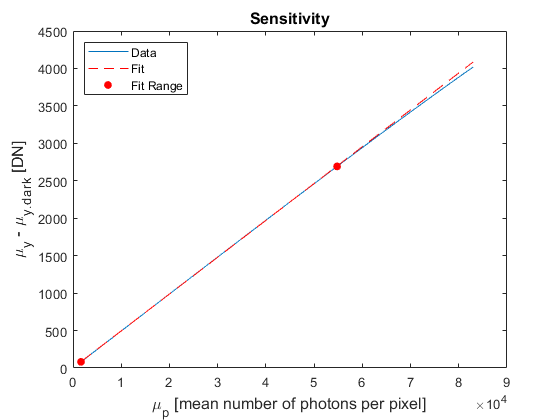

R = 0.0492

p_sat = 8.1323e+04

[R,p_sat] = sensitivity_curve_mono(imgarray_mv,1659.66)

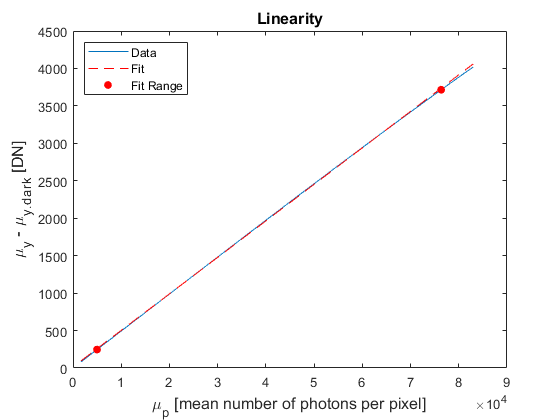

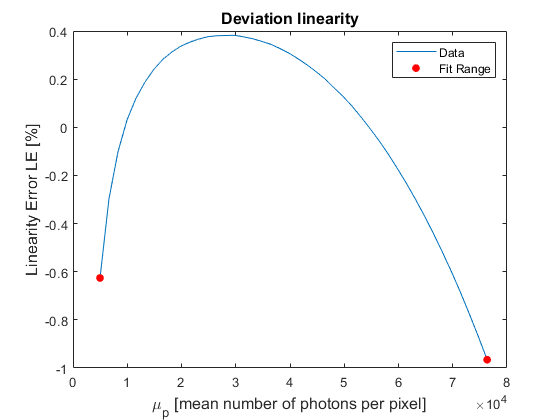

LE_min = -0.9656

LE_max = 0.3818

[LE_min,LE_max] = linearity(imgarray_mv,1659.66)

[DSNU,PRNU,sv_50,sv_dark,avg_img_dark,avg_img_50,var_stack_dark,var_stack_50] = DSNU_PRNU_3dmat(images_dark,images_50,K)

DSNU = 22.0316

PRNU = 0.9669

sv_50 = 395.9462

sv_dark = 4.5257

avg_img_dark =    30.8100   31.0100   29.7600   31.8200   30.4800   32.1100   28.6300   28.2800   29.0900   30.5200   32.1200   27.0800   26.4100   28.6600   26.7000   31.1200   30.3100   26.7400   28.8500   29.8500   30.9900   30.5400   28.8300   30.1400   28.3100   32.8900   31.3500   27.0300   29.8600   31.0200   32.5500   31.5000   27.6400   26.8200   29.7400   29.7200   30.4000   24.9000   27.4400   26.1700   30.3800   27.4200   28.4500   27.7500   28.7100   32.2100   30.5600   27.9500   28.8100   31.4100
   32.2200   27.5300   29.9800   29.0400   32.6600   29.6100   26.2700   26.8000   30.4600   31.2200   28.4700   29.7800   26.3000   24.8100   31.7300   27.8500   26.1600   25.2700   27.5400   31.4200   31.3500   28.4600   28.9000   30.1300   31.4600   31.1300   29.8700   29.6900   29.1500   33.4300   29.1100   25.5000   27.2000   29.4100   30.1300   26.4300   30.7300   25.5100   24.9800   29.4500   26.2900   26.4700   28.7900   31.2800   28.3200   30.5700   29.2400   26.2500   3

avg_img_50 = 	1.0e+03 *

    1.9971    2.0234    1.9997    2.0163    2.0288    2.0076    2.0156    2.0013    2.0108    1.9928    2.0142    2.0089    2.0113    2.0059    1.9960    2.0083    2.0018    2.0338    2.0128    1.9915    2.0238    2.0084    2.0005    2.0326    2.0145    2.0089    1.9929    2.0130    2.0255    2.0177    2.0362    2.0129    2.0137    2.0128    2.0059    2.0171    2.0303    2.0229    2.0043    2.0258    2.0183    2.0244    2.0177    2.0309    2.0306    2.0332    2.0234    2.0295    2.0197    2.0146
    2.0193    2.0185    2.0203    2.0129    2.0329    2.0025    2.0052    2.0197    2.0157    2.0168    2.0332    2.0217    2.0047    2.0130    2.0250    2.0091    2.0089    1.9922    2.0162    2.0022    2.0101    2.0131    2.0096    2.0188    2.0306    2.0151    1.9840    2.0243    2.0183    2.0272    2.0198    2.0072    2.0050    2.0215    2.0168    2.0193    2.0262    2.0362    2.0113    2.0161    2.0131    2.0265    2.0141    2.0280    2.0237    2.0311    2.0295    

var_stack_dark = 9.0819

var_stack_50 = 210.0982


p_min= absolute_sensitivity_threshold(R/K,var_dark,K)

p_min = 62.2267


e_sat = saturation_capacity(R/K,p_sat)

e_sat = 4.1432e+04

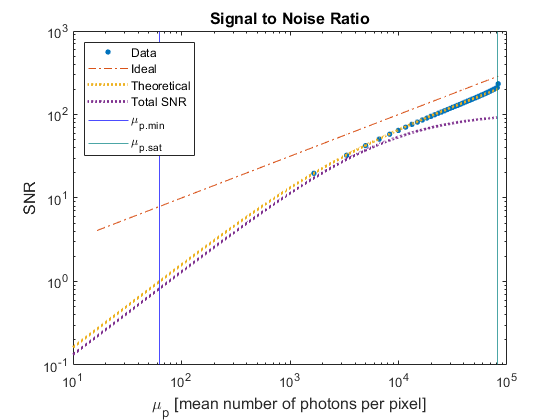

SNR_max = 203.5497

DR = 1.3069e+03

[SNR_max,DR] = plot_SNR(imgarray_mv,1659.66,p_min,p_sat,e_sat,temp_dark,1/12,K,R/K,DSNU,PRNU)

output=fourier_eq49(avg_img_dark)

output =    1.7505 - 0.0674i  -0.0947 + 1.4360i  -1.8792 - 0.1677i   0.7216 - 0.3940i   1.9661 - 0.9314i  -2.8545 + 0.4183i   0.3011 + 3.2668i  -0.8538 + 1.1286i   0.0534 + 1.1497i   0.9045 - 1.1370i  -0.0644 - 3.0468i   0.4003 - 0.4634i  -0.5759 + 0.2902i  -0.3802 - 0.9863i   0.0565 + 1.0807i  -0.4971 - 1.0191i  -0.5989 + 1.3530i   0.6012 + 1.9339i  -0.8474 + 0.4246i  -0.7385 + 1.6831i   2.1215 + 0.3368i   0.5662 + 0.5587i   0.0722 + 0.5407i  -0.0224 + 2.1187i  -2.4243 +10.1236i  -0.9584 -13.4361i  -1.2787 - 2.7088i   0.4973 - 2.0720i  -1.0672 - 2.7711i  -0.6992 + 0.7204i  -0.7929 - 0.2701i  -0.4717 - 1.2139i   0.2031 - 1.3553i  -0.1403 - 2.7556i  -0.8370 - 2.3598i  -0.8165 + 1.5577i  -1.0207 - 0.3881i  -0.1711 + 1.7107i   0.1186 - 1.6620i   0.8694 - 3.0079i  -0.4598 - 0.0860i  -1.0538 - 0.7915i   0.7067 + 0.8604i   0.1546 - 1.0185i   0.0745 - 1.8248i  -0.9948 - 1.5875i  -0.1704 - 0.0193i  -0.8450 - 2.1258i   0.6951 + 0.5537i  -2.6467 + 0.3396i
   0.1824 - 1.1291i  -1.0713 - 0.9280i  

p=power_spectrum_eq50(output)

p =     2.4565    2.5521    2.6283    2.4989    2.5309    2.6173    2.6220    2.2705    2.5212    2.5934    2.6372    2.6623    2.5180    2.6290    2.7484    2.6119    2.7926    2.9925    3.2019    3.3143    4.0421    4.7315    7.3106   15.3353   93.0383  208.6082   19.6067    8.1144    5.1403    3.7532    3.2564    3.2289    2.9307    2.7438    2.9003    2.6969    2.7632    2.4960    2.7296    2.7140    2.7460    2.3053    2.3801    2.5066    2.4685    2.6768    2.3416    2.4092    2.3065    2.5330


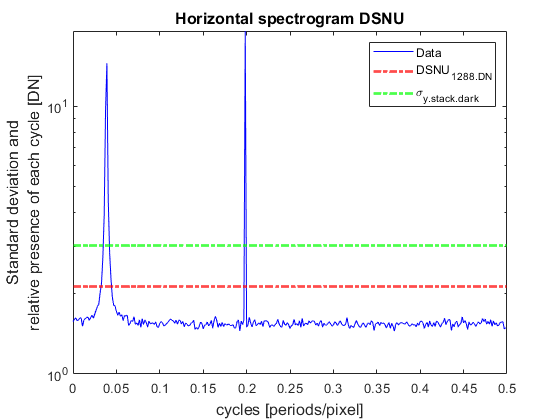

DSNU_var_white_dark = 2.3924

[DSNU_var_white_dark]=spectrogram(avg_img_dark,avg_img_50,'horizontal','DSNU',DSNU,var_stack_dark,K)

% var_3=spectrogram(avg_img_dark,avg_img_50,'vertical','DSNU',DSNU,var_stack_dark,K)

% var_2=spectrogram(avg_img_dark,avg_img_50,'vertical','PRNU',PRNU,var_stack_50,K)

% var_4=spectrogram(avg_img_dark,avg_img_50,'horizontal','PRNU',PRNU,var_stack_50,K)

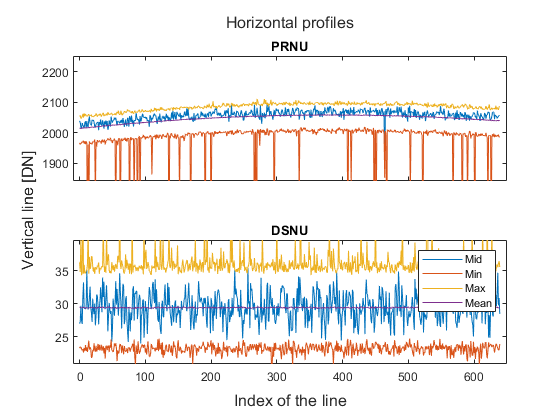

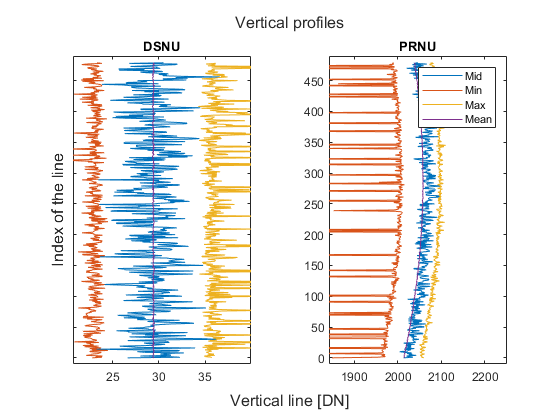

profiles(avg_img_dark,avg_img_50)

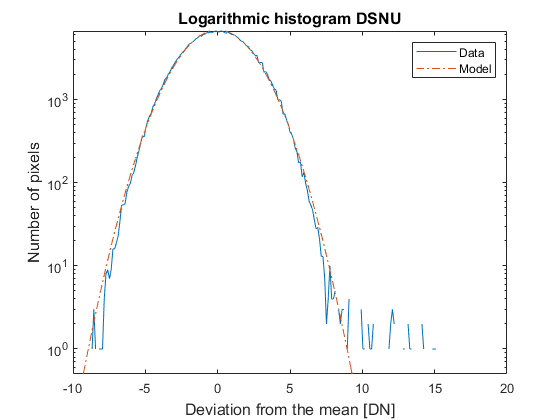

var_nw = 0.1913

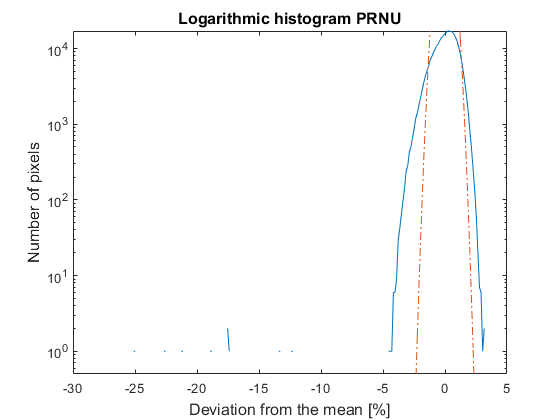

logarithmic_histogram(avg_img_dark,avg_img_50,100,sv_dark,sv_50)